%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% General Framework for the detection and removal of motion artifacts from
% the PPG data of Maxem. 
% SPROJ OF:
% Mohammad Afaq 
% Sheraz Hassan 
% Salaar Ali Asad
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear global;
clear all;

global fs_avg window Overlap_perc BandPassfilter maxem_recordings_directory results_direc Walking SlightArmMovement Typing Writing plot_data save_to_file


fs=512;  % Sample Rate
Avg=8;   % Sampling Average
fs_avg=fs/Avg;  %Averaged Sampling Rate 64 Hz

window=64*3/4;
Overlap_perc=90;
BandPassfilter=butterworth

BandPassfilter =          FilterStructure: 'Direct-Form II, Second-Order Sections'      
              Arithmetic: 'double'                                     
               sosMatrix: [1 0 -1 1 -1.6917043661597 0.711648515536758]
             ScaleValues: [0.144175742231621;1]                        
     OptimizeScaleValues: true                                         
        PersistentMemory: false                                        
                                                                       


maxem_recordings_directory= 'C:\Users\Mohammad Afaq\OneDrive\Documents\Afaq Documents\Personal\Educational\LUMS\EE Thesis - LUMS\sproj research\All Datasets (With pre-processing algorithms)\SPROJ-2\Maxem_Raw';
results_direc='C:\Users\Mohammad Afaq\OneDrive\Documents\LUMS-Shared\ShareAbleSprojFolder\sproj research\Results\Results2\';


Walking='2-Walking\';
SlightArmMovement='3-SlightArmMovement\';
Typing='5-Typing\';
Writing='6-Writing\';
plot_data=true;
save_to_file=true;



type = '0'

t =     0.0156    0.0313    0.0469    0.0625    0.0781    0.0938    0.1094    0.1250    0.1406    0.1563    0.1719    0.1875    0.2031    0.2188    0.2344    0.2500    0.2656    0.2813    0.2969    0.3125    0.3281    0.3438    0.3594    0.3750    0.3906    0.4063    0.4219    0.4375    0.4531    0.4688    0.4844    0.5000    0.5156    0.5313    0.5469    0.5625    0.5781    0.5938    0.6094    0.6250    0.6406    0.6563    0.6719    0.6875    0.7031    0.7188    0.7344    0.7500    0.7656    0.7813


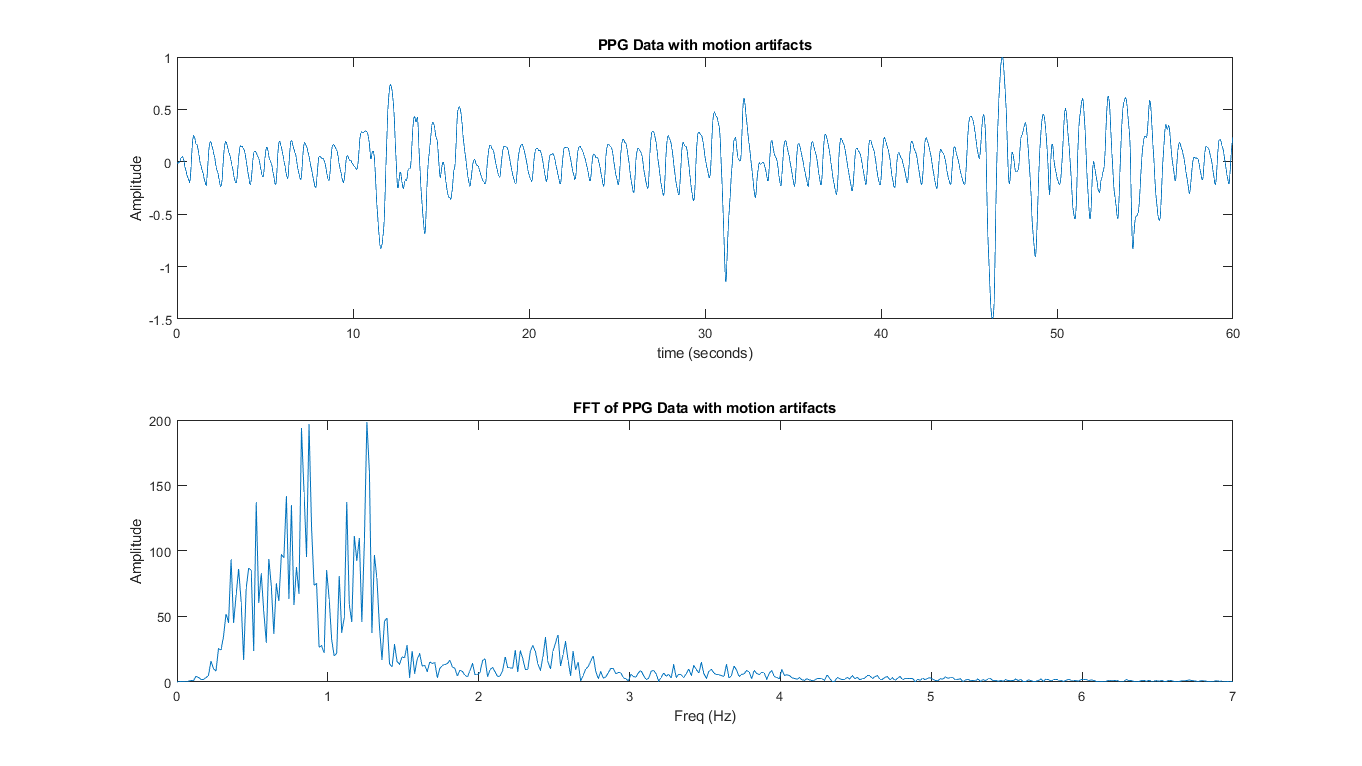

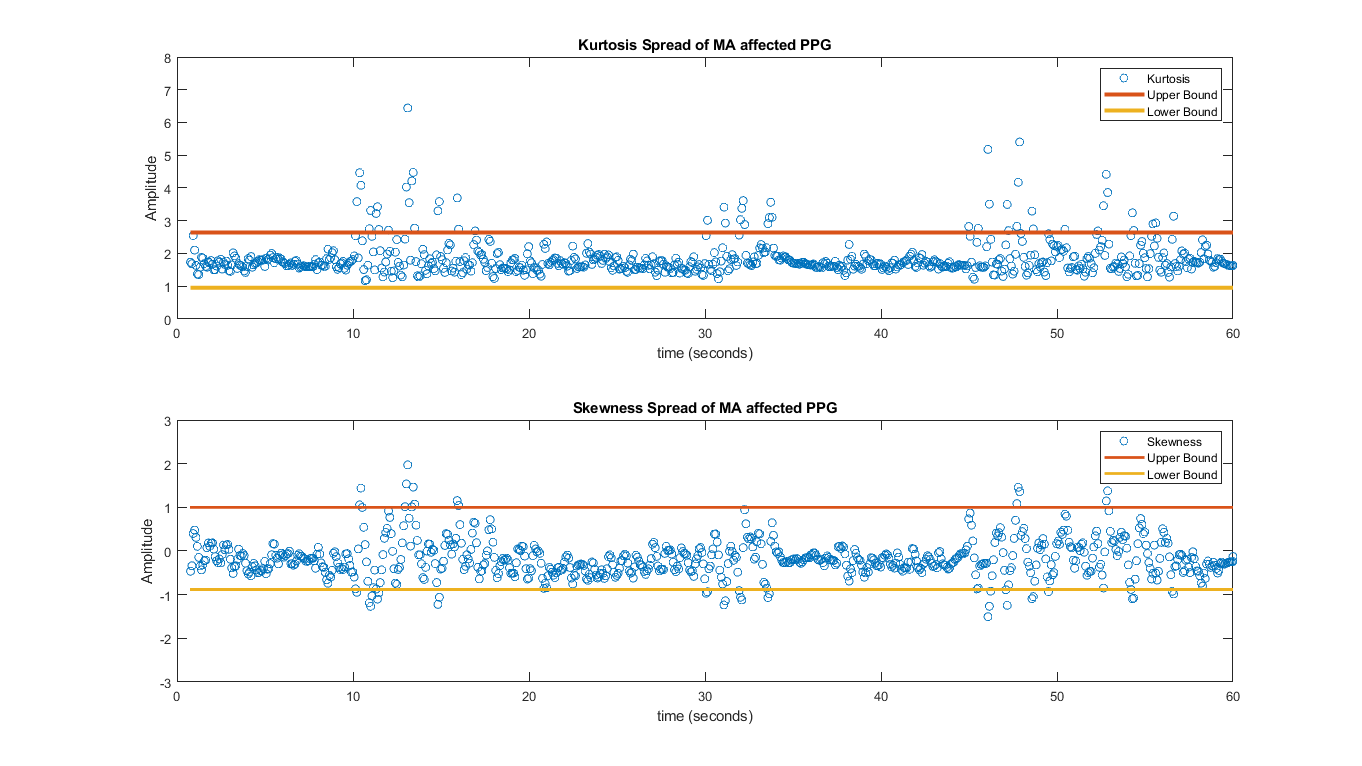

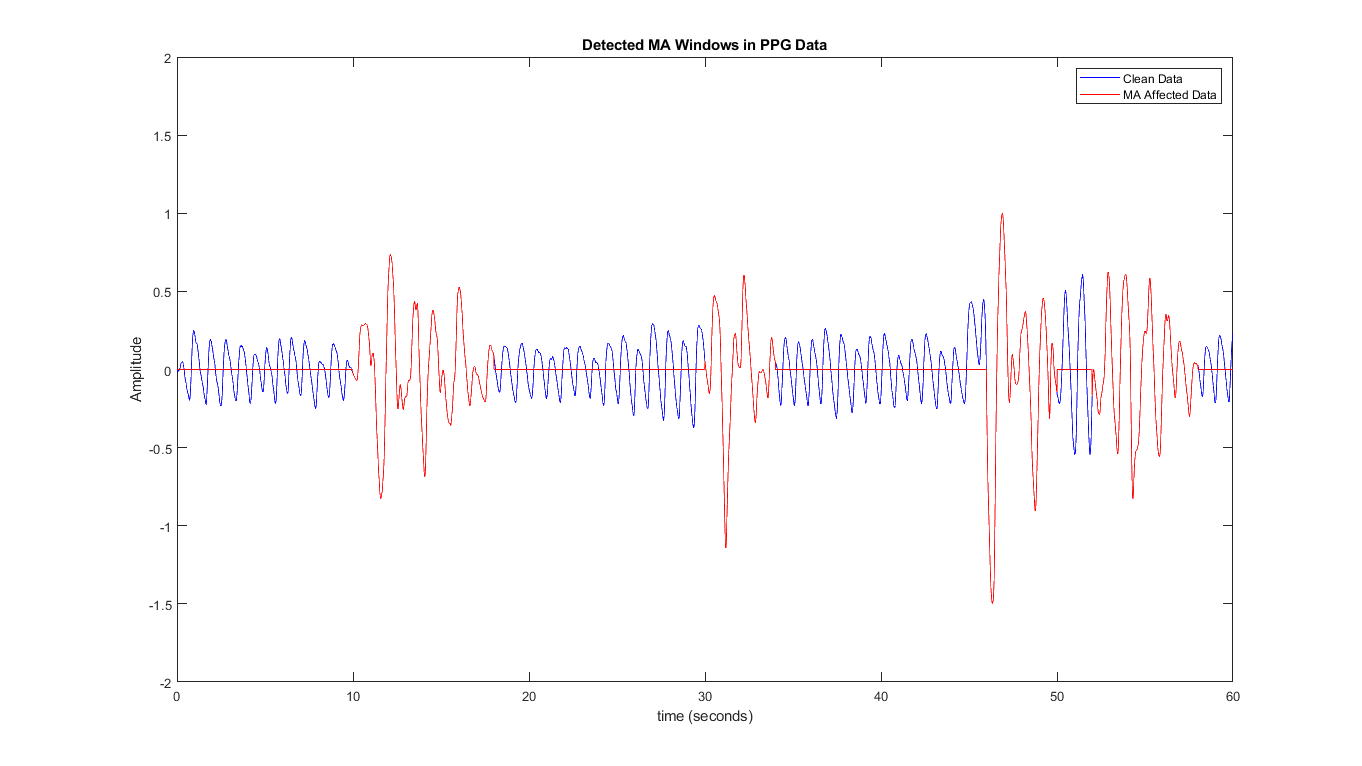

temp =     30    34


temp =     46    50


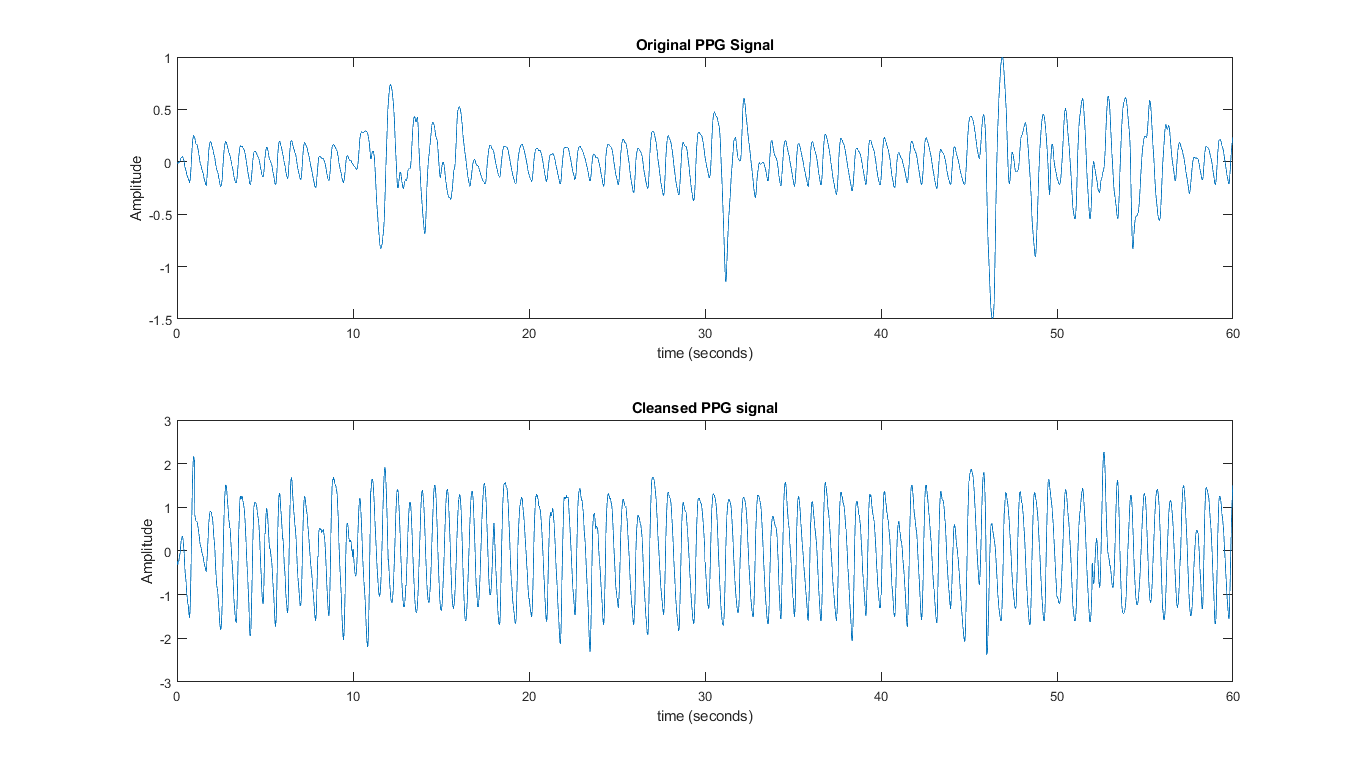

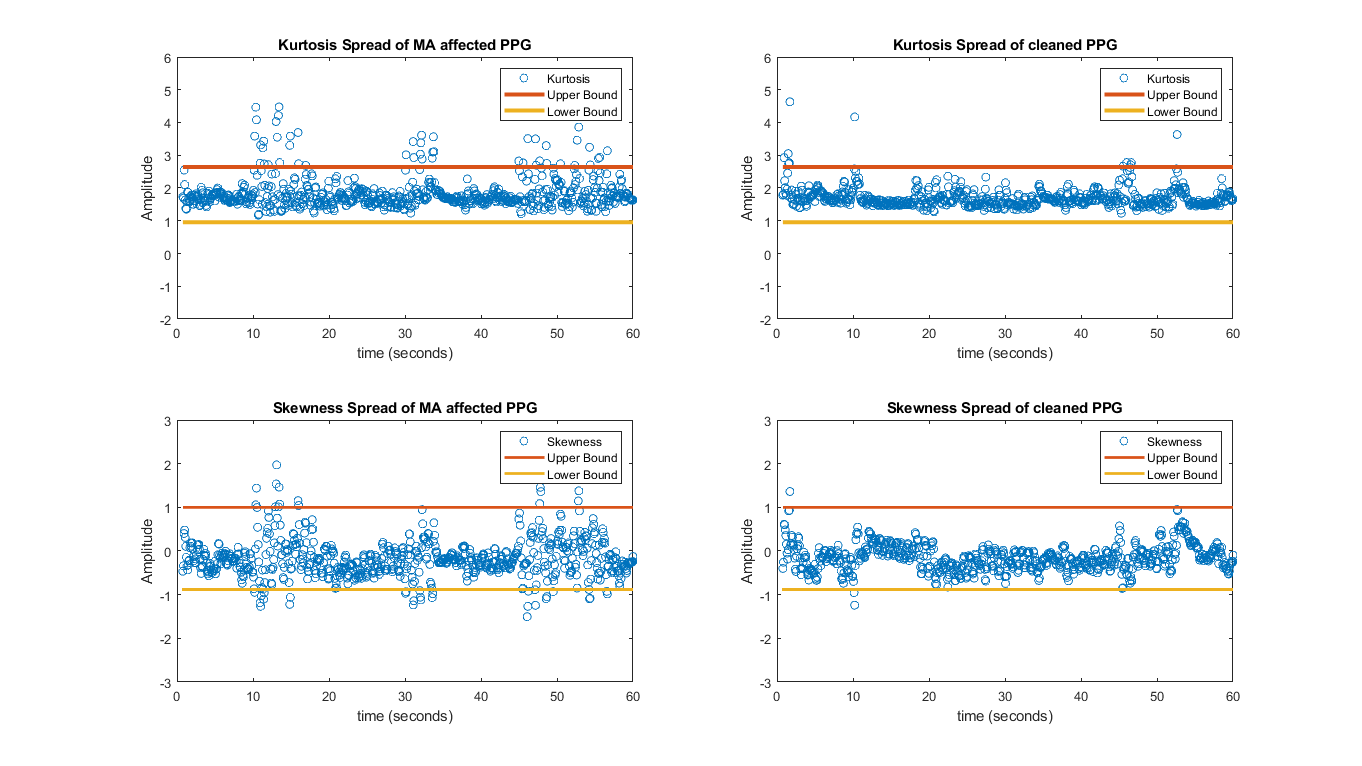

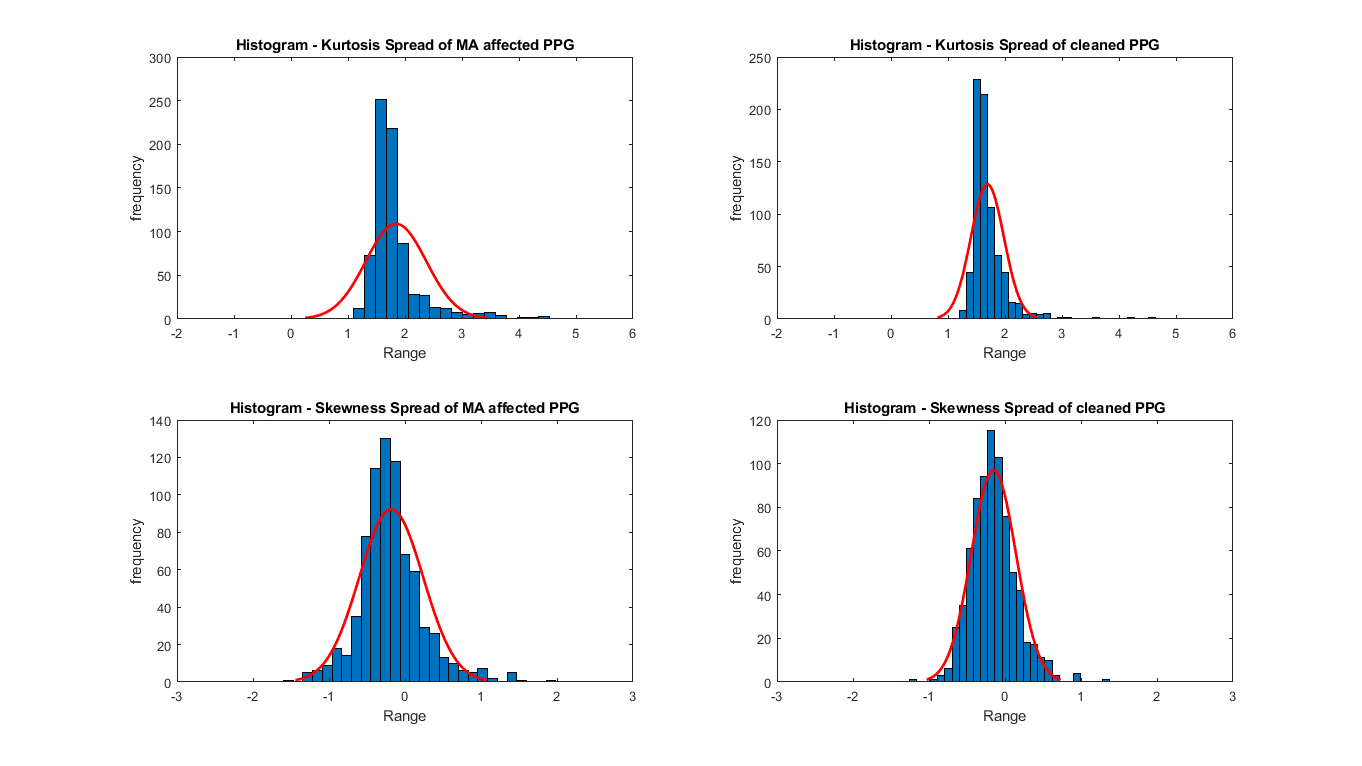

%%upload reference signal with no motion artifacts for calibration. 
filename='M1-4-1.csv';

subject='1';
calib_wind=[1 20];
[PPG_ref_data_1,perf_ref_data_1,training_data_1,CI_Kur_1,CI_skew_1]=calibrate_data(filename,subject,calib_wind);


excercise=Walking;
[Features_after_1_2,Features_before_1_2]=Process_and_obtain_results(subject,excercise,CI_Kur_1,CI_skew_1,PPG_ref_data_1);
excercise=SlightArmMovement;
[Features_after_1_3,Features_before_1_3]=Process_and_obtain_results(subject,excercise,CI_Kur_1,CI_skew_1,PPG_ref_data_1);
excercise=Typing;
[Features_after_1_5,Features_before_1_5]=Process_and_obtain_results(subject,excercise,CI_Kur_1,CI_skew_1,PPG_ref_data_1);
excercise=Writing;
[Features_after_1_6,Features_before_1_6]=Process_and_obtain_results(subject,excercise,CI_Kur_1,CI_skew_1,PPG_ref_data_1);



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
filename='M2-1-1.csv';
subject='2';
calib_wind=[10 35];
[PPG_ref_data_2,perf_ref_data_2,training_data_2,CI_Kur_2,CI_skew_2]=calibrate_data(filename,subject,calib_wind);


excercise=Walking;
[Features_after_2_2,Features_before_2_2]=Process_and_obtain_results(subject,excercise,CI_Kur_2,CI_skew_2,PPG_ref_data_2);
excercise=SlightArmMovement;
[Features_after_2_3,Features_before_2_3]=Process_and_obtain_results(subject,excercise,CI_Kur_2,CI_skew_2,PPG_ref_data_2);
excercise=Typing;
[Features_after_2_5,Features_before_2_5]=Process_and_obtain_results(subject,excercise,CI_Kur_2,CI_skew_2,PPG_ref_data_2);
excercise=Writing;
[Features_after_2_6,Features_before_2_6]=Process_and_obtain_results(subject,excercise,CI_Kur_2,CI_skew_2,PPG_ref_data_2);



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
filename='M3-1-1.csv';
subject='3';
calib_wind=[10 35];
[PPG_ref_data_3,perf_ref_data_3,training_data_3,CI_Kur_3,CI_skew_3]=calibrate_data(filename,subject,calib_wind);



%excercise=Walking;
%[Features_after_3_2,Features_before_3_2]=Process_and_obtain_results(subject,excercise,CI_Kur_3,CI_skew_3,PPG_ref_data_3);
excercise=SlightArmMovement;
[Features_after_3_3,Features_before_3_3]=Process_and_obtain_results(subject,excercise,CI_Kur_3,CI_skew_3,PPG_ref_data_3);
excercise=Typing;
[Features_after_3_5,Features_before_3_5]=Process_and_obtain_results(subject,excercise,CI_Kur_3,CI_skew_3,PPG_ref_data_3);
excercise=Writing;
[Features_after_3_6,Features_before_3_6]=Process_and_obtain_results(subject,excercise,CI_Kur_3,CI_skew_3,PPG_ref_data_3);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
filename='M4-1-1.csv';
subject='4';
calib_wind=[10 35];
[PPG_ref_data_4,perf_ref_data_4,training_data_4,CI_Kur_4,CI_skew_4]=calibrate_data(filename,subject,calib_wind);



excercise=Walking;
[Features_after_4_2,Features_before_4_2]=Process_and_obtain_results(subject,excercise,CI_Kur_4,CI_skew_4,PPG_ref_data_4);
excercise=SlightArmMovement;
[Features_after_4_3,Features_before_4_3]=Process_and_obtain_results(subject,excercise,CI_Kur_4,CI_skew_4,PPG_ref_data_4);
excercise=Typing;
[Features_after_4_5,Features_before_4_5]=Process_and_obtain_results(subject,excercise,CI_Kur_4,CI_skew_4,PPG_ref_data_4);
excercise=Writing;
[Features_after_4_6,Features_before_4_6]=Process_and_obtain_results(subject,excercise,CI_Kur_4,CI_skew_4,PPG_ref_data_4);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
filename='M5-1-1.csv';
subject='5';
calib_wind=[10 35];
[PPG_ref_data_5,perf_ref_data_5,training_data_5,CI_Kur_5,CI_skew_5]=calibrate_data(filename,subject,calib_wind);



excercise=Walking;
[Features_after_5_2,Features_before_5_2]=Process_and_obtain_results(subject,excercise,CI_Kur_5,CI_skew_5,PPG_ref_data_5);
excercise=SlightArmMovement;
[Features_after_5_3,Features_before_5_3]=Process_and_obtain_results(subject,excercise,CI_Kur_5,CI_skew_5,PPG_ref_data_5);
excercise=Typing;
[Features_after_5_5,Features_before_5_5]=Process_and_obtain_results(subject,excercise,CI_Kur_5,CI_skew_5,PPG_ref_data_5);
excercise=Writing;
[Features_after_5_6,Features_before_5_6]=Process_and_obtain_results(subject,excercise,CI_Kur_5,CI_skew_5,PPG_ref_data_5);



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
filename='M6-1-1.csv';
subject='6';
calib_wind=[10 30];
[PPG_ref_data_6,perf_ref_data_6,training_data_6,CI_Kur_6,CI_skew_6]=calibrate_data(filename,subject,calib_wind);



excercise=Walking;
[Features_after_6_2,Features_before_6_2]=Process_and_obtain_results(subject,excercise,CI_Kur_6,CI_skew_6,PPG_ref_data_6);
excercise=SlightArmMovement;
[Features_after_6_3,Features_before_6_3]=Process_and_obtain_results(subject,excercise,CI_Kur_6,CI_skew_6,PPG_ref_data_6);
excercise=Typing;
[Features_after_6_5,Features_before_6_5]=Process_and_obtain_results(subject,excercise,CI_Kur_6,CI_skew_6,PPG_ref_data_6);
excercise=Writing;
[Features_after_6_6,Features_before_6_6]=Process_and_obtain_results(subject,excercise,CI_Kur_6,CI_skew_6,PPG_ref_data_6);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
filename='M7-1-1.csv';
subject='7';
calib_wind=[10 35];
[PPG_ref_data_7,perf_ref_data_7,training_data_7,CI_Kur_7,CI_skew_7]=calibrate_data(filename,subject,calib_wind);



excercise=Walking;
[Features_after_7_2,Features_before_7_2]=Process_and_obtain_results(subject,excercise,CI_Kur_4,CI_skew_7,PPG_ref_data_7);
excercise=SlightArmMovement;
[Features_after_7_3,Features_before_7_3]=Process_and_obtain_results(subject,excercise,CI_Kur_4,CI_skew_7,PPG_ref_data_7);
excercise=Typing;
[Features_after_7_5,Features_before_7_5]=Process_and_obtain_results(subject,excercise,CI_Kur_4,CI_skew_7,PPG_ref_data_7);
excercise=Writing;
[Features_after_7_6,Features_before_7_6]=Process_and_obtain_results(subject,excercise,CI_Kur_4,CI_skew_7,PPG_ref_data_7);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
filename='M8-1-1.csv';
subject='8';
calib_wind=[10 35];
[PPG_ref_data_8,perf_ref_data_8,training_data_8,CI_Kur_8,CI_skew_8]=calibrate_data(filename,subject,calib_wind);



excercise=Walking;
[Features_after_8_2,Features_before_8_2]=Process_and_obtain_results(subject,excercise,CI_Kur_8,CI_skew_8,PPG_ref_data_8);
excercise=SlightArmMovement;
[Features_after_8_3,Features_before_8_3]=Process_and_obtain_results(subject,excercise,CI_Kur_8,CI_skew_8,PPG_ref_data_8);
excercise=Typing;
[Features_after_8_5,Features_before_8_5]=Process_and_obtain_results(subject,excercise,CI_Kur_8,CI_skew_8,PPG_ref_data_8);
excercise=Writing;
[Features_after_8_6,Features_before_8_6]=Process_and_obtain_results(subject,excercise,CI_Kur_8,CI_skew_8,PPG_ref_data_8);



Excercise_2_before=[Features_before_1_2;Features_before_2_2;Features_before_4_2;Features_before_5_2;Features_before_6_2;Features_before_7_2;Features_before_8_2];
Excercise_2_after=[Features_after_1_2;Features_after_2_2;Features_after_4_2;Features_after_5_2;Features_after_6_2;Features_after_7_2;Features_after_8_2];

Excercise_3_before=[Features_before_1_3;Features_before_2_3;Features_before_3_3;Features_before_4_3;Features_before_5_3;Features_before_6_3;Features_before_7_3;Features_before_8_3];
Excercise_3_after=[Features_after_1_3;Features_after_2_3;Features_after_3_3;Features_after_4_3;Features_after_5_3;Features_after_6_3;Features_after_7_3;Features_after_8_3;];

Excercise_5_before=[Features_before_1_5;Features_before_2_5;Features_before_3_5;Features_before_4_5;Features_before_5_5;Features_before_6_5;Features_before_7_5;Features_before_8_5];
Excercise_5_after=[Features_after_1_5;Features_after_2_5;Features_after_3_5;Features_after_4_5;Features_after_5_5;Features_after_6_5;Features_after_7_5;Features_after_8_5];

Excercise_6_before=[Features_before_1_6;Features_before_2_6;Features_before_3_6;Features_before_4_6;Features_before_5_6;Features_before_6_6;Features_before_7_6;Features_before_8_6];
Excercise_6_after=[Features_after_1_6;Features_after_2_6;Features_after_3_6;Features_after_4_6;Features_after_5_6;Features_after_6_6;Features_after_7_6;Features_after_8_6];



cd(results_direc);
if plot_data
    figure('Position', get(0, 'Screensize'));
    sgtitle("Movement - Walking")
    subplot(2,2,1)
    histfit(Excercise_2_before(:,1),100)
    xlim([-2 6])
    xlabel('range')
    ylabel('frequency')
    title("Overall Kurtosis Spread before processing")
    
    subplot(2,2,2)
    histfit(Excercise_2_after(:,1),100)
    xlim([-2 6])
    xlabel('range')
    ylabel('frequency')
    title("Overall Kurtosis Spread Original Signal after processing")

    
    subplot(2,2,3)
    histfit(Excercise_2_before(:,2),100)
    xlim([-3 3])
    xlabel('range')
    ylabel('frequency')
    title("Overall Skewness Spread before processing")
    
    subplot(2,2,4)
    histfit(Excercise_2_after(:,2),100)
    xlim([-3 3])
    xlabel('range')
    ylabel('frequency')
    title("Overall Skewness Spread Original Signal after processing")
    
    
    if save_to_file
        exportgraphics(gcf,'Overall_distribution_Walking.png','Resolution',600)
        saveas(gcf,'Overall_distribution_Walking.fig')
    end
end


if plot_data
    figure('Position', get(0, 'Screensize'));
    sgtitle("Movement - SlightArmMovement")
    subplot(2,2,1)
    histfit(Excercise_3_before(:,1),100)
    xlim([-2 6])
    xlabel('range')
    ylabel('frequency')
    title("Overall Kurtosis Spread before processing")
    
    subplot(2,2,2)
    histfit(Excercise_3_after(:,1),100)
    xlim([-2 6])
    xlabel('range')
    ylabel('frequency')
    title("Overall Kurtosis Spread Original Signal after processing")

    
    subplot(2,2,3)
    histfit(Excercise_3_before(:,2),100)
    xlim([-3 3])
    xlabel('range')
    ylabel('frequency')
    title("Overall Skewness Spread before processing")
    
    subplot(2,2,4)
    histfit(Excercise_3_after(:,2),100)
    xlim([-3 3])
    xlabel('range')
    ylabel('frequency')
    title("Overall Skewness Spread Original Signal after processing")
    
    if save_to_file
        exportgraphics(gcf,'Overall_distribution_SlightArmMovement.png','Resolution',600)
        saveas(gcf,'Overall_distribution_SlightArmMovement.fig')
    end
end



if plot_data
    figure('Position', get(0, 'Screensize'));
    sgtitle("Movement - Typing")
    subplot(2,2,1)
    histfit(Excercise_5_before(:,1),100)
    xlim([-2 6])
    xlabel('range')
    ylabel('frequency')
    title("Overall Kurtosis Spread before processing")
    
    subplot(2,2,2)
    histfit(Excercise_5_after(:,1),100)
    xlim([-2 6])
    xlabel('range')
    ylabel('frequency')
    title("Overall Kurtosis Spread Original Signal after processing")

    
    subplot(2,2,3)
    histfit(Excercise_5_before(:,2),100)
    xlim([-3 3])
    xlabel('range')
    ylabel('frequency')
    title("Overall Skewness Spread before processing")
    
    subplot(2,2,4)
    histfit(Excercise_5_after(:,2),100)
    xlim([-3 3])
    xlabel('range')
    ylabel('frequency')
    title("Overall Skewness Spread Original Signal after processing")
    
    if save_to_file
        exportgraphics(gcf,'Overall_distribution_Typing.png','Resolution',600)
        saveas(gcf,'Overall_distribution_Typing.fig')
    end
end


if plot_data
    figure('Position', get(0, 'Screensize'));
    sgtitle("Movement - Writing")
    subplot(2,2,1)
    histfit(Excercise_6_before(:,1),100)
    xlim([-2 6])
    xlabel('range')
    ylabel('frequency')
    title("Overall Kurtosis Spread before processing")
    
    subplot(2,2,2)
    histfit(Excercise_6_after(:,1),100)
    xlim([-2 6])
    xlabel('range')
    ylabel('frequency')
    title("Overall Kurtosis Spread Original Signal after processing")

    
    subplot(2,2,3)
    histfit(Excercise_6_before(:,2),100)
    xlim([-3 3])
    xlabel('range')
    ylabel('frequency')
    title("Overall Skewness Spread before processing")
    
    subplot(2,2,4)
    histfit(Excercise_6_after(:,2),100)
    xlim([-3 3])
    xlabel('range')
    ylabel('frequency')
    title("Overall Skewness Spread Original Signal after processing")
    
    if save_to_file
        exportgraphics(gcf,'Overall_distribution_Writing.png','Resolution',600)
        saveas(gcf,'Overall_distribution_Writing.fig')
    end
end



perfomance_matrix_Kur=[];
perfomance_matrix_Skew=[];



%%Calculating performance index for each subject and each excercise
%subject 1
subject_1_2_kur=perf_index(CI_Kur_1,Features_after_1_2,Features_before_1_2,'Kur');
subject_1_2_skew=perf_index(CI_skew_1,Features_after_1_2,Features_before_1_2,'Skew');

subject_1_3_kur=perf_index(CI_Kur_1,Features_after_1_3,Features_before_1_3,'Kur');
subject_1_3_skew=perf_index(CI_skew_1,Features_after_1_3,Features_before_1_3,'Skew');

subject_1_5_kur=perf_index(CI_Kur_1,Features_after_1_5,Features_before_1_5,'Kur');
subject_1_5_skew=perf_index(CI_skew_1,Features_after_1_5,Features_before_1_5,'Skew');

subject_1_6_kur=perf_index(CI_Kur_1,Features_after_1_6,Features_before_1_6,'Kur');
subject_1_6_skew=perf_index(CI_skew_1,Features_after_1_6,Features_before_1_6,'Skew');

temp=[];
temp=[temp  subject_1_2_kur];
temp=[temp  subject_1_3_kur];
temp=[temp  subject_1_5_kur];
temp=[temp  subject_1_6_kur];
perfomance_matrix_Kur=[perfomance_matrix_Kur ; temp];


temp=[];
temp=[temp  subject_1_2_skew];
temp=[temp  subject_1_3_skew];
temp=[temp  subject_1_5_skew];
temp=[temp  subject_1_6_skew];
perfomance_matrix_Skew=[perfomance_matrix_Skew ; temp];


%subject 2
subject_2_2_kur=perf_index(CI_Kur_2,Features_after_2_2,Features_before_2_2,'Kur');
subject_2_2_skew=perf_index(CI_skew_2,Features_after_2_2,Features_before_2_2,'Skew');

subject_2_3_kur=perf_index(CI_Kur_2,Features_after_2_3,Features_before_2_3,'Kur');
subject_2_3_skew=perf_index(CI_skew_2,Features_after_2_3,Features_before_2_3,'Skew');

subject_2_5_kur=perf_index(CI_Kur_2,Features_after_2_5,Features_before_2_5,'Kur');
subject_2_5_skew=perf_index(CI_skew_2,Features_after_2_5,Features_before_2_5,'Skew');

subject_2_6_kur=perf_index(CI_Kur_2,Features_after_2_6,Features_before_2_6,'Kur');
subject_2_6_skew=perf_index(CI_skew_2,Features_after_2_6,Features_before_2_6,'Skew');

temp=[]
temp=[temp  subject_2_2_kur];
temp=[temp  subject_2_3_kur];
temp=[temp  subject_2_5_kur];
temp=[temp  subject_2_6_kur];
perfomance_matrix_Kur=[perfomance_matrix_Kur ; temp];

temp=[];
temp=[temp  subject_2_2_skew];
temp=[temp  subject_2_3_skew];
temp=[temp  subject_2_5_skew];
temp=[temp  subject_2_6_skew];
perfomance_matrix_Skew=[perfomance_matrix_Skew ; temp];

%subject 3
%subject_3_2_kur=perf_index(CI_Kur_3,Features_after_3_2,Features_before_3_2,'Kur')
%subject_3_2_skew=perf_index(CI_skew_3,Features_after_3_2,Features_before_3_2,'Skew')
subject_3_2_kur=[0 0];
subject_3_2_skew=[0 0];

subject_3_3_kur=perf_index(CI_Kur_3,Features_after_3_3,Features_before_3_3,'Kur');
subject_3_3_skew=perf_index(CI_skew_3,Features_after_3_3,Features_before_3_3,'Skew');

subject_3_5_kur=perf_index(CI_Kur_3,Features_after_3_5,Features_before_3_5,'Kur');
subject_3_5_skew=perf_index(CI_skew_3,Features_after_3_5,Features_before_3_5,'Skew');

subject_3_6_kur=perf_index(CI_Kur_3,Features_after_3_6,Features_before_3_6,'Kur');
subject_3_6_skew=perf_index(CI_skew_3,Features_after_3_6,Features_before_3_6,'Skew');

temp=[];
temp=[temp  subject_3_2_kur];
temp=[temp  subject_3_3_kur];
temp=[temp  subject_3_5_kur];
temp=[temp  subject_3_6_kur];
perfomance_matrix_Kur=[perfomance_matrix_Kur ; temp];

temp=[];
temp=[temp  subject_3_2_skew];
temp=[temp  subject_3_3_skew];
temp=[temp  subject_3_5_skew];
temp=[temp  subject_3_6_skew];
perfomance_matrix_Skew=[perfomance_matrix_Skew ; temp];


%subject 4
subject_4_2_kur=perf_index(CI_Kur_4,Features_after_4_2,Features_before_4_2,'Kur');
subject_4_2_skew=perf_index(CI_skew_4,Features_after_4_2,Features_before_4_2,'Skew');

subject_4_3_kur=perf_index(CI_Kur_4,Features_after_4_3,Features_before_4_3,'Kur');
subject_4_3_skew=perf_index(CI_skew_4,Features_after_4_3,Features_before_4_3,'Skew');

subject_4_5_kur=perf_index(CI_Kur_4,Features_after_4_5,Features_before_4_5,'Kur');
subject_4_5_skew=perf_index(CI_skew_4,Features_after_4_5,Features_before_4_5,'Skew');

subject_4_6_kur=perf_index(CI_Kur_4,Features_after_4_6,Features_before_4_6,'Kur');
subject_4_6_skew=perf_index(CI_skew_4,Features_after_4_6,Features_before_4_6,'Skew');

temp=[];
temp=[temp  subject_4_2_kur];
temp=[temp  subject_4_3_kur];
temp=[temp  subject_4_5_kur];
temp=[temp  subject_4_6_kur];
perfomance_matrix_Kur=[perfomance_matrix_Kur ; temp];

temp=[];
temp=[temp  subject_4_2_skew];
temp=[temp  subject_4_3_skew];
temp=[temp  subject_4_5_skew];
temp=[temp  subject_4_6_skew];
perfomance_matrix_Skew=[perfomance_matrix_Skew ; temp];

%subject 5
subject_5_2_kur=perf_index(CI_Kur_5,Features_after_5_2,Features_before_5_2,'Kur');
subject_5_2_skew=perf_index(CI_skew_5,Features_after_5_2,Features_before_5_2,'Skew');

subject_5_3_kur=perf_index(CI_Kur_5,Features_after_5_3,Features_before_5_3,'Kur');
subject_5_3_skew=perf_index(CI_skew_5,Features_after_5_3,Features_before_5_3,'Skew');

subject_5_5_kur=perf_index(CI_Kur_5,Features_after_5_5,Features_before_5_5,'Kur');
subject_5_5_skew=perf_index(CI_skew_5,Features_after_5_5,Features_before_5_5,'Skew');

subject_5_6_kur=perf_index(CI_Kur_5,Features_after_5_6,Features_before_5_6,'Kur');
subject_5_6_skew=perf_index(CI_skew_5,Features_after_5_6,Features_before_5_6,'Skew');

temp=[];
temp=[temp  subject_5_2_kur];
temp=[temp  subject_5_3_kur];
temp=[temp  subject_5_5_kur];
temp=[temp  subject_5_6_kur];
perfomance_matrix_Kur=[perfomance_matrix_Kur ; temp];

temp=[];
temp=[temp  subject_5_2_skew];
temp=[temp  subject_5_3_skew];
temp=[temp  subject_5_5_skew];
temp=[temp  subject_5_6_skew];

perfomance_matrix_Skew=[perfomance_matrix_Skew ; temp];

%subject 6
subject_6_2_kur=perf_index(CI_Kur_6,Features_after_6_2,Features_before_6_2,'Kur');
subject_6_2_skew=perf_index(CI_skew_6,Features_after_6_2,Features_before_6_2,'Skew');

subject_6_3_kur=perf_index(CI_Kur_6,Features_after_6_3,Features_before_6_3,'Kur');
subject_6_3_skew=perf_index(CI_skew_6,Features_after_6_3,Features_before_6_3,'Skew');

subject_6_5_kur=perf_index(CI_Kur_6,Features_after_6_5,Features_before_6_5,'Kur');
subject_6_5_skew=perf_index(CI_skew_6,Features_after_6_5,Features_before_6_5,'Skew');

subject_6_6_kur=perf_index(CI_Kur_6,Features_after_6_6,Features_before_6_6,'Kur');
subject_6_6_skew=perf_index(CI_skew_6,Features_after_6_6,Features_before_6_6,'Skew');

temp=[];
temp=[temp  subject_6_2_kur];
temp=[temp  subject_6_3_kur];
temp=[temp  subject_6_5_kur];
temp=[temp  subject_6_6_kur];
perfomance_matrix_Kur=[perfomance_matrix_Kur ; temp];

temp=[];
temp=[temp  subject_6_2_skew];
temp=[temp  subject_6_3_skew];
temp=[temp  subject_6_5_skew];
temp=[temp  subject_6_6_skew];
perfomance_matrix_Skew=[perfomance_matrix_Skew ; temp];

%subject 7
subject_7_2_kur=perf_index(CI_Kur_7,Features_after_7_2,Features_before_7_2,'Kur');
subject_7_2_skew=perf_index(CI_skew_7,Features_after_7_2,Features_before_7_2,'Skew');

subject_7_3_kur=perf_index(CI_Kur_7,Features_after_7_3,Features_before_7_3,'Kur');
subject_7_3_skew=perf_index(CI_skew_7,Features_after_7_3,Features_before_7_3,'Skew');

subject_7_5_kur=perf_index(CI_Kur_7,Features_after_7_5,Features_before_7_5,'Kur');
subject_7_5_skew=perf_index(CI_skew_7,Features_after_7_5,Features_before_7_5,'Skew');

subject_7_6_kur=perf_index(CI_Kur_7,Features_after_7_6,Features_before_7_6,'Kur');
subject_7_6_skew=perf_index(CI_skew_7,Features_after_7_6,Features_before_7_6,'Skew');

temp=[];
temp=[temp  subject_7_2_kur];
temp=[temp  subject_7_3_kur];
temp=[temp  subject_7_5_kur];
temp=[temp  subject_7_6_kur];
perfomance_matrix_Kur=[perfomance_matrix_Kur ; temp];

temp=[];
temp=[temp  subject_7_2_skew];
temp=[temp  subject_7_3_skew];
temp=[temp  subject_7_5_skew];
temp=[temp  subject_7_6_skew];
perfomance_matrix_Skew=[perfomance_matrix_Skew ; temp];

%subject 8
subject_8_2_kur=perf_index(CI_Kur_8,Features_after_8_2,Features_before_8_2,'Kur');
subject_8_2_skew=perf_index(CI_skew_8,Features_after_8_2,Features_before_8_2,'Skew');

subject_8_3_kur=perf_index(CI_Kur_8,Features_after_8_3,Features_before_8_3,'Kur');
subject_8_3_skew=perf_index(CI_skew_8,Features_after_8_3,Features_before_8_3,'Skew');

subject_8_5_kur=perf_index(CI_Kur_8,Features_after_8_5,Features_before_8_5,'Kur');
subject_8_5_skew=perf_index(CI_skew_8,Features_after_8_5,Features_before_8_5,'Skew');

subject_8_6_kur=perf_index(CI_Kur_8,Features_after_8_6,Features_before_8_6,'Kur');
subject_8_6_skew=perf_index(CI_skew_8,Features_after_8_6,Features_before_8_6,'Skew');

temp=[];
temp=[temp  subject_8_2_kur];
temp=[temp  subject_8_3_kur];
temp=[temp  subject_8_5_kur];
temp=[temp  subject_8_6_kur];
perfomance_matrix_Kur=[perfomance_matrix_Kur ; temp];

temp=[];
temp=[temp  subject_8_2_skew];
temp=[temp  subject_8_3_skew];
temp=[temp  subject_8_5_skew];
temp=[temp  subject_8_6_skew];
perfomance_matrix_Skew=[perfomance_matrix_Skew ; temp];

display(perfomance_matrix_Kur)

display(perfomance_matrix_Skew)


T = table;
T.Before_walking = squeeze(perfomance_matrix_Kur(:,1));
T.After_waking = squeeze(perfomance_matrix_Kur(:,2));
T.Before_armmovement = squeeze(perfomance_matrix_Kur(:,3));
T.After_armmovement = squeeze(perfomance_matrix_Kur(:,4));
T.Before_typing = squeeze(perfomance_matrix_Kur(:,5));
T.After_typing = squeeze(perfomance_matrix_Kur(:,6));
T.Before_writing = squeeze(perfomance_matrix_Kur(:,7));
T.After_writing = squeeze(perfomance_matrix_Kur(:,8));
save('Kurtosis_table.mat', 'T')


T = table;
T.Before_walking = squeeze(perfomance_matrix_Skew(:,1));
T.After_waking = squeeze(perfomance_matrix_Skew(:,2));
T.Before_armmovement = squeeze(perfomance_matrix_Skew(:,3));
T.After_armmovement = squeeze(perfomance_matrix_Skew(:,4));
T.Before_typing = squeeze(perfomance_matrix_Skew(:,5));
T.After_typing = squeeze(perfomance_matrix_Skew(:,6));
T.Before_writing = squeeze(perfomance_matrix_Skew(:,7));
T.After_writing = squeeze(perfomance_matrix_Skew(:,8));

save('Skewness_table.mat', 'T')

function [features_after,features_before]=Process_and_obtain_results(subject,excercise,CI_Kur,CI_skew,PPG_ref_data)
    global fs_avg window Overlap_perc BandPassfilter maxem_recordings_directory results_direc Walking SlightArmMovement Typing Writing plot_data save_to_file
    
    if strcmp(excercise,Walking)
        type='2';
    elseif strcmp(excercise,SlightArmMovement)
        type='3';
    elseif strcmp(excercise,Typing)
        type='5';
    elseif strcmp(excercise,Writing)
        type='6';
    end

    filename=append('M',subject,'-',type,'-1.csv');
    cd(maxem_recordings_directory)
    Test_data=xlsread(filename);
    
    dir=append(results_direc,"Subject",subject,"\",excercise);
    
    cd(dir)
    PPG_data=(Test_data(:,5));
    [perf_data, PPG_data] = pre_process(BandPassfilter,PPG_data,fs_avg);
    %ACC_x=(Test_data(:,7));
    %ACC_y=(Test_data(:,8));
    %ACC_z=(Test_data(:,9));
    %plot(PPG_data)
    
    if plot_data
        figure('Position', get(0, 'Screensize'));
        subplot(2,1,1)
        plot(obtain_time(PPG_data),PPG_data)
        title('PPG Data with motion artifacts')
        xlim([0 85])
        xlabel('time (seconds)')
        ylabel('Amplitude')
        subplot(2,1,2)
        freq_plot(PPG_data,fs_avg)
        title('FFT of PPG Data with motion artifacts')
        xlabel('Freq (Hz)')
        ylabel('Amplitude')
        xlim([0 7])
        if save_to_file
            exportgraphics(gcf,'Dataandfreqplot.png','Resolution',600)
            saveas(gcf,'Dataandfreqplot.fig')
        end
    end
    
    
    
    [X_test]=obtain_features(PPG_data,window,Overlap_perc,fs_avg);
    CI_skew_=CI_skew.*ones(length(X_test(:,3)),2);
    CI_kur_=CI_Kur.*ones(length(X_test(:,3)),2);
    features_before=X_test;
    
    if plot_data
        figure('Position', get(0, 'Screensize'))
        subplot(2,1,1);
        plot_stats(CI_Kur,X_test,'Kurtosis')
        xlim([0 85])
        title('Kurtosis Spread of MA affected PPG')
        legend('Kurtosis','Upper Bound','Lower Bound')
        subplot(2,1,2)
        plot_stats(CI_skew,X_test,'Skewness')
        xlim([0 85])
        title('Skewness Spread of MA affected PPG')
        legend('Skewness','Upper Bound','Lower Bound')
        if save_to_file
        exportgraphics(gcf,'KurandSkew.png','Resolution',600)
        saveas(gcf,'KurandSkew.fig')
        end
    end
    
    %%detecting windows where MA affected our signal
    jump=2;
    windows=get_windows(X_test,jump,CI_Kur,CI_skew);
    
    if plot_data
        figure('Position', get(0, 'Screensize'))
        display_detections(PPG_data,windows)
        ylim([-2 2])
        title('Detected MA Windows in PPG Data')
        legend('Clean Data','MA Affected Data')
        if save_to_file
            exportgraphics(gcf,'windows.png','Resolution',600)
            saveas(gcf,'windows.fig')
        end
    end
    
    %% cleaning signal
    %Synthetic_cal_data=Averaging_window(PPG_ref_data,[10 15]);
    
    [cleansed_data]=cleansignal(windows,PPG_data,PPG_ref_data);
    
    if plot_data
        figure('Position', get(0, 'Screensize'))
        subplot(2,1,1)
        time=1:1:length(PPG_data);
        time=time/64;
        plot(time,PPG_data)
        xlim([0 85])
        title('Original PPG Signal')
        xlabel('time (seconds)')
        ylabel('Amplitude')
        
        
        
        subplot(2,1,2)
        time=1:1:length(cleansed_data);
        time=time/64;
        plot(time,cleansed_data)
        xlim([0 85])
        title('Cleansed PPG signal')
        xlabel('time (seconds)')
        ylabel('Amplitude')
        
        if save_to_file
            exportgraphics(gcf,'cleansed_data.png','Resolution',600)
            saveas(gcf,'cleansed_data.fig')
        end
    end
    
    

    [out]=obtain_features(cleansed_data,window,Overlap_perc,fs_avg);
    features_after=out;
    
    CI_skew_=CI_skew.*ones(length(out(:,3)),2);
    CI_kur_=CI_Kur.*ones(length(out(:,3)),2);
   
    if plot_data
        figure('Position', get(0, 'Screensize'))
        subplot(2,2,1)
        plot_stats(CI_Kur,X_test,'Kurtosis')
        title('Kurtosis Spread of MA affected PPG')
        legend('Kurtosis','Upper Bound','Lower Bound')
        ylim([-2 6])
        
        subplot(2,2,3)
        plot_stats(CI_skew,X_test,'Skewness')
        title('Skewness Spread of MA affected PPG')
        legend('Skewness','Upper Bound','Lower Bound')
        ylim([-3 3])
        
        subplot(2,2,2)
        plot_stats(CI_Kur,out,'Kurtosis')
        title('Kurtosis Spread of cleaned PPG')
        legend('Kurtosis','Upper Bound','Lower Bound')
        ylim([-2 6])
        
        subplot(2,2,4)
        plot_stats(CI_skew,out,'Skewness')
        title('Skewness Spread of cleaned PPG')
        legend('Skewness','Upper Bound','Lower Bound')
        ylim([-3 3])
        if save_to_file
            exportgraphics(gcf,'Kur_skew_beforevsafter.png','Resolution',600)
            saveas(gcf,'Kur_skew_beforevsafter.fig')
        end
    end
    
    
    if plot_data
        figure('Position', get(0, 'Screensize'))
        subplot(2,2,1)
        histfit(X_test(:,1))
        xlabel('Range')
        ylabel('frequency')
        xlim([-2 6])
        title('Histogram - Kurtosis Spread of MA affected PPG')
        subplot(2,2,3)
        
        histfit(X_test(:,2))
        xlabel('Range')
        ylabel('frequency')
        xlim([-3 3])
        title('Histogram - Skewness Spread of MA affected PPG')
        
        
        subplot(2,2,2)
        histfit(out(:,1))
        xlabel('Range')
        ylabel('frequency')
        xlim([-2 6])
        title('Histogram - Kurtosis Spread of cleaned PPG')
        
        subplot(2,2,4)
        histfit(out(:,2))
        xlabel('Range')
        ylabel('frequency')
        xlim([-3 3])
        title('Histogram - Skewness Spread of cleaned PPG')
        
        if save_to_file
            exportgraphics(gcf,'hist.png','Resolution',600)
            saveas(gcf,'hist.fig')
        end
    end
    
end

function [PPG_ref_data,perf_ref_data,training_data,CI_Kur,CI_skew]=calibrate_data(filename,subject,calib_wind)
    global fs_avg window Overlap_perc BandPassfilter maxem_recordings_directory results_direc Walking SlightArmMovement Typing Writing plot_data save_to_file    

    cd(maxem_recordings_directory)
    Ref_data=xlsread(filename);
    Ref_data=(Ref_data(:,3))/2;
    Ref_data=Ref_data(calib_wind(1)*64:calib_wind(2)*64);
    [perf_ref_data, PPG_ref_data] = pre_process(BandPassfilter,Ref_data,fs_avg);
    [training_data]=obtain_features(PPG_ref_data,window,Overlap_perc,fs_avg);
    %figure
    %plot(PPG_ref_data)
    
   
    dir=append(results_direc,"Subject",subject);
    cd(dir) 
    
    if plot_data==true
        figure('Position', get(0, 'Screensize'));
        subplot(2,1,1)
        
        plot(obtain_time(PPG_ref_data),PPG_ref_data)
        xlabel('time (seconds)')
        ylabel('Amplitude')
        title('Reference PPG data')
        xlim([0 round(length(PPG_ref_data)/64 - 0.5)])
        subplot(2,1,2)
        plot(obtain_time(perf_ref_data),perf_ref_data)
        xlabel('time (seconds)')
        ylabel('Amplitude')
        title('Corresponding Perfusion data')
        xlim([0 round(length(perf_ref_data)/64 - 0.5)])
        if save_to_file==true
            exportgraphics(gcf,'Calibration_data.png','Resolution',600)
            saveas(gcf,'Calibration_data.fig')
        end
    end
    
    
    
    
    
    %% creating Kurtosis and Skewness bounds. We will be using these statistics for the detection of motion artifacts
    
    CI_Kur= createbound(training_data(:,1));
    CI_Kur_=CI_Kur.*ones(length(training_data(:,1)),2);
    
    CI_skew= createbound(training_data(:,2));
    CI_skew_=CI_skew.*ones(length(training_data(:,2)),2);
    
    if plot_data==true
        figure('Position', get(0, 'Screensize'));
        subplot(2,1,1)
        plot_stats(CI_Kur,training_data,'Kurtosis')
        ylim([0 3])
        legend('Kurtosis','Upper Bound','Lower Bound')
        
        
        subplot(2,1,2)
        plot_stats(CI_skew,training_data,'Skewness')
        ylim([-2 2])
        legend('Skewness','Upper Bound','Lower Bound')
        
        sgtitle('Spread of kurtosis and Skewness for our initial reference PPG signal over time')
        if save_to_file==true
            exportgraphics(gcf,'Kur_Skew_Calib.png','Resolution',600)
            saveas(gcf,'Kur_Skew_Calib.fig')
        end
    end
    
end

function [PPG_data]=cleansignal(windows,PPG_data,PPG_ref_cal_data)
    dim=size(windows);
    total_windows=length(windows(:,1));
    %display(windows);
    for i=1:total_windows
        if total_windows==1
            init=windows(1);
            fin=windows(2);
        else
            init=windows(i,1);
            fin=windows(i,2);
        end

        
        if fin*64 < length(PPG_data)
            
            if fin-init<5 %% far wrist motion
                temp=[init fin]
                
                if init>6 
                    replace=Averaging_window(PPG_data,temp);  
                else
                    replace=Averaging_window(PPG_ref_cal_data,[10 10+(fin-init)]);
                end
                
                with=PPG_data(init*64:fin*64,1);
                difference=replace(1)-with(1);
                replace=replace-difference;
                replace=normalize(replace); 
                replace=(replace-min(replace))/(max(replace)-min(replace));
                replace=2*replace-1;
                PPG_data(init*64:fin*64,1)=replace;
                
            else
                if fin-init>1
                    temp=[init fin];
                    
                    if init>6 
                        ref_g_data=Averaging_window(PPG_data,temp);  
                    else
                        ref_g_data=Averaging_window(PPG_ref_cal_data,[10 10+(fin-init)]);
                    end
                    g_data=PPG_data(init*64:fin*64,1);
                    [g_data] = AdaptiveFilter(ref_g_data,g_data,1,0.01,16,0.99,1);
                    g_data=sgolayfilt(g_data,3,33);
                    HRF=HeartRate(g_data);
                    g_data=NotchFilter(g_data,HRF,64);
                    perf=sgolayfilt(g_data,2,4*64 +1);
                    g_data=g_data-perf;
                    fil=butterworth;
                    g_data=filter(fil,g_data);
                    %g_data=sgolayfilt(g_data(:,1),4,65);
                    PPG_data(init*64:fin*64,1)=g_data;
                end
            end
        end
    end
    PPG_data=norm_signal(PPG_data,windows);
    
    PPG_data=norm_windows(PPG_data);
    
end


function [PPG_Data] = AdaptiveFilter(PPG_sig,Ref_sig,ref_type,mu,len,forf,inic)
    d1 = PPG_sig;
    d2 = Ref_sig;
    if ref_type == 1
        ref = d1-d2;
        ref=sgolayfilt(ref,1,65);
        
        mu = mu;
        rls1 = dsp.RLSFilter(len,'Method','Sliding-window RLS','ForgettingFactor',forf,'InitialInverseCovariance',inic);
        [x1,~] = rls1(d1,ref);
        [x2,~] = rls1(d2,ref);
    
        [Ta] = fundamental_period_extraction(x1);
        [new_ref_sig1,new_ref_sig2] = B_optim(x1,x2,ref,Ta,mu);
        rls2 = dsp.RLSFilter(len,'Method','Sliding-window RLS','ForgettingFactor',forf,'InitialInverseCovariance',inic);
        [ppg_red,~] = rls2(new_ref_sig2,x1);
    else
        ref = d2;

        rls1 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [x1,~] = rls1(d1,ref);
        [x2,~] = rls1(d2,ref);
        rls2 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [ppg_red,~] = rls2(d1-x1,x1);
    end


    PPG_Data = d1 - ppg_red;
end


function [new_ref_sig1,new_ref_sig2] = B_optim(x1,x2,ref_sig,Ta,mu)
    
    rv = mean(x2./ref_sig);
    s_as = x1 - rv*x2;
    
    lms = dsp.LMSFilter('Length',64,'Method','LMS','StepSize',mu);
    [est_Sas] = lms(x1,s_as);
    est_Sas2 = x1 - est_Sas;
    filter_coeff = lpc(est_Sas2,Ta);
    
    a = (mean(x1.*x1,'all')-rv*mean(x1.*x2,'all'))/mean(s_as,'all');
    b = (a*rv)/(1-a);
    x3 =[];
    for i=1:length(x2)
        if x2(i)>x1(i)
            x3(i) = 0.95*x2(i);
        elseif x2(i)<x1(i)
            x3(i) = 1.05*x2(i);
        else
            x3(i) = x2(i);
        end
    end
        b = 1.05;
    
    
    new_ref_sig1 =  est_Sas2;
    new_ref_sig2 = x1 - x3'; 
    
end


function [Ta] = fundamental_period_extraction(x1)
    x = xcorr(x1);
    l = length(x);
    t_max = floor(l/3);
    t = 1:t_max;
    y = zeros(l,1);
    z = [];
    for i = 1:t_max
        y(i) = 1;
        y(2*i) = 0.9;
        y(3*i) = 0.8;
        z1 = y.*x;
        Z = fft(z1);
        pow = Z.*conj(Z);
        pow_acc = sum(Z);
        z = [z pow_acc];
    end
    [~,ind] = max(z);
    Ta = ind;
end

function [replace] = Averaging_window(PPG,windows)

    if (windows(1)-5)>0
        data=PPG((windows(1)-5)*64:(windows(1)-1)*64);
    else
        display("need more data to calibrate")
        return
    end
    double_der=diff(diff(data));
    [peaks,locs]=findpeaks(double_der,'MinPeakHeight',0.01,"MinPeakDistance",32);
    
    distances=[];
    for i=1:length(locs)-1
        distances=[distances abs(locs(i)-locs(i+1))];
    end
    
    len=min(distances);
    PPG_sum=[];
    for i=1:length(locs)-1
        PPG_sum=[PPG_sum data(locs(i):locs(i)+len)];
    end
    
    sum=zeros(len+1,1);
    for i=1:length(distances)
        sum=sum+PPG_sum(:,i);
    end
    
    Averaged=sum/length(distances);
    
    window=windows(2)-windows(1);
    samples=window*64;
    d=length(Averaged);
    bias=Averaged(length(Averaged))-Averaged(1);
    
    
    second_sample=PPG(windows(1)*64+10);
    first_sample=PPG(windows(1)*64);
    last_sample=PPG((windows(1)*64)-10);
    initial_index=0;
    
    if second_sample>last_sample 
        grad='positive';
        if first_sample>last_sample
            
            %display('positive')
            for i=2:length(Averaged)-1
                gradi=Averaged(i+1)-Averaged(i-1);
                if gradi>0
                    if Averaged(i)<second_sample && Averaged(i)>first_sample
                        initial_index=i;
                    end
                end
            end
        end
    end
    
    if second_sample<last_sample 
        grad='negative';
        if first_sample<last_sample
            
            %display('negative')
            for i=2:length(Averaged)-1
                gradi=Averaged(i+1)-Averaged(i-1);
                if gradi<0
                    if Averaged(i)>second_sample && Averaged(i)<first_sample
                        initial_index=i;
                    end
                end
            end
        end
    end
    
    if initial_index==0
        if grad=="positive"
            initial_index=round(length(Averaged)/2);
        elseif grad=="negative"
            initial_index=1;
        end
    end
    replace=[Averaged(initial_index:length(Averaged))];
    used=length(Averaged)-initial_index;

    
    choice=[];
    i=1;
    while(used<samples)
        if (samples-used)<d
            choice=Averaged(1:samples-used);
        else
            choice=Averaged;
        end
        choice=choice+i*bias;
        replace=[replace;choice];
        used=used+length(choice);
        i=i+1;
    end
    
    if length(replace)>65
        trend=sgolayfilt(replace,1,1*64+1);
    else
        trend=sgolayfilt(replace,1,15);
    end
    
    replace=replace-trend;
    
    shift=replace(1)-last_sample;
    replace=replace-shift;

end


function [feature_matrix,time]=obtain_features(data,window_size,Overlap,fs)
    Input_data=data;
    window=window_size;
    Overlap_perc=Overlap;
    
    current_pos=1;
    prev_pos=1;
    last_iter=0;
    
    Kur=[];
    Skew=[];
    Standard_dev=[];
    time=[];
    
    len_signal=length(Input_data);
    
    while 1
        if (prev_pos+window) < len_signal
            current_pos=prev_pos+window;
        else
            current_pos=len_signal;
            last_iter=1;
        end
        
        data_segment=Input_data(prev_pos:current_pos);
        Kur=[Kur kurtosis(data_segment)];
        Skew=[Skew skewness(data_segment)];
        Standard_dev=[Standard_dev std(data_segment)];
        
        if last_iter==0
            time=[time current_pos/fs];
        elseif last_iter==1
            time=[time len_signal/fs];
            break
        end
        
        prev_pos=current_pos- round((Overlap_perc/100) *window);
    end
    
    Kur=transpose(Kur);
    Skew=transpose(Skew);
    Standard_dev=transpose(Standard_dev);
    time=transpose(time);

    
    feature_matrix=[Kur,Skew,time];

end

function khirki = get_windows(X_test,jump,CI_Kur,CI_skew)

    window=[];
    time_init=0;
    time_final=0;
    windows=[];
    i=1;
    
    while i < length(X_test(:,1))
        if ((X_test(i,1)>CI_Kur(1)) ||  (X_test(i,1)<CI_Kur(2))) && ((X_test(i,2)>CI_skew(1)) ||  (X_test(i,2)<CI_skew(2)))
            time_init=round(X_test(i,3)-0.5);
            if time_init==0
                time_init=1;
            end
            window=[];
            prev_time=time_init;
            time_final=0;
            index=i;
            
            while 1
                count_motion=0;
                if prev_time + jump > X_test(length(X_test(:,1)),3)
                    break
                end
                while X_test(index,3) < prev_time + jump
                    if ((X_test(index,1)>CI_Kur(1)) ||  (X_test(index,1)<CI_Kur(2))) && ((X_test(index,2)>CI_skew(1)) ||  (X_test(index,2)<CI_skew(2)))
                        count_motion=count_motion+1; 
                    end
                    index=index+1;
                    if index > length(X_test(:,1))
                        index=length(X_test(:,1));
                        break
                    end
                end
                if count_motion<1
                    break
                else
                    
                end
                prev_time=round(X_test(index,3));              
            end
            time_final=prev_time;

            if index> length(X_test(:,1))
                window=[time_init length(X_test(:,1))];
                break
            else
                window=[time_init time_final];
            end
            
            if (window(1)~=window(2))
                windows=[windows;window];
            end
            i=index;
        end
        i=i+1;
    end
    khirki=windows;
end

function [perf, PPG] = pre_process(fil,data,fs)
    perf=sgolayfilt(data,2,4*fs +1);
    PPG=data-perf;
    PPG=-1*PPG;
    PPG=filter(fil,PPG);
    %PPG=(PPG-min(PPG))/(max(PPG)-min(PPG));
    %PPG=2*PPG-1;
    PPG=normalize(PPG); 
    PPG=PPG/max(PPG);
end

function Hd = butterworth
    Fs = 64;  
    N   = 2;   
    Fc1 = 0.6;  
    Fc2 = 4;    
    h  = fdesign.bandpass('N,F3dB1,F3dB2', N, Fc1, Fc2, Fs);
    Hd = design(h, 'butter');
end

function time=obtain_time(data)
    fs=64;
    time=1:1:length(data);
    time=time/fs;
end

function CI= createbound(data)
    m=mean(data);
    s=std(data);
    CI=[m+2*s m-2*s]; %bound that contains 95% of the data
end

function freq_plot(data,fs)
    FM = (abs(fftshift(fft(data)))); 	
    FF = linspace(-fs/2,fs/2,length(FM)); 
    plot(FF,FM)
    xlim([0.05 10])
end

function plot_stats(stat,data,koc)
    CI=stat.*ones(length(data),2);
    if koc=='Kurtosis'
        plot(data(:,3),data(:,1),'o')
        hold on
        plot(data(:,3),CI,'LineWidth',3)
        title('Kurtosis Spread')
        xlabel('time (seconds)')
        ylabel('Amplitude')
        ylim([0 8])
        %legend('Kurtosis','Upper Bound','Lower Bound')
    elseif koc=='Skewness'
        plot(data(:,3),data(:,2),'o')
        hold on
        plot(data(:,3),CI,'LineWidth',2)
        title('Skewness Spread')
        xlabel('time (seconds)')
        ylabel('Amplitude')
        ylim([-3 3])
        %legend('Skewness','Upper Bound','Lower Bound')
    end
    
    %legend('Skewness','Upper Bound','Lower Bound')

end

function display_detections(data,windows)
    detected_visual=zeros(length(data),1);
    if length(windows(:,1))==1
        detected_visual(windows(1)*64:windows(2)*64)=data((windows(1)*64:windows(2)*64));
    else
        for i=1:length(windows)
            detected_visual(windows(i,1)*64:windows(i,2)*64)=data((windows(i,1)*64:windows(i,2)*64));
        end
    end
    
    plot(obtain_time(data),data,'b')
    hold on
    plot(obtain_time(detected_visual),detected_visual,'r')

    xlabel('time (seconds)')
    ylabel('Amplitude')
    title('PPG signal with MA')
    %legend('Clean Data','MA Affected Data')
end

function temp=norm_signal(temp,windows)
    wds=length(windows(:,1));
    
    i=0;
    while i<wds+1
        if i == 0
            if wds==1
                temp(1:windows(1)*64-1)=normalize(temp(1:windows(1)*64-1)); 
            else
                temp(1:windows(1,1)*64-1)=normalize(temp(1:windows(1,1)*64-1));  
            end
            
        else
            if wds==1
                temp(windows(1)*64:windows(2)*64)=normalize(temp(windows(1)*64:windows(2)*64));   
            else
               temp(windows(i,1)*64:windows(i,2)*64)=normalize(temp(windows(i,1)*64:windows(i,2)*64));   
            end
            
        end
        i=i+1;
    end
    
    i=1;
    while i<wds+1
        
        if i~=wds
            if wds==1
                temp(windows(2)*64+1:windows(1)*64-1)=normalize(temp(windows(2)*64+1:windows(1)*64-1));   
            else
                temp(windows(i,2)*64+1:windows(i+1,1)*64-1)=normalize(temp(windows(i,2)*64+1:windows(i+1,1)*64-1));   
            end
            
        else
            if wds==1
                temp(windows(2)*64+1:length(temp))=normalize(temp(windows(2)*64+1:length(temp)));
            else
                temp(windows(i,2)*64+1:length(temp))=normalize(temp(windows(i,2)*64+1:length(temp)));   
            end
            
        end
        i=i+1;
    end
    temp=(temp-min(temp))/(max(temp)-min(temp));
    temp=2*temp-1;
end

function [PPG_sig_proc] = NotchFilter(PPG_sig,HRF,fs)
    w0 = HRF/(fs/2);
    bw = w0/45;
    [b,a] = iirnotch(w0,bw);
    
    w1 = (HRF*2)/(fs/2);
    bw1 = w1/90;
    [b1,a1] = iirnotch(w1,bw1);
    
    proc_sig = filter(b,a,PPG_sig);
    proc_sig1 = filter(b1,a1,proc_sig);
    
    PPG_sig_proc = PPG_sig - proc_sig1;
    PPG_sig_proc = normalize(PPG_sig_proc);
end

function [HRF] = HeartRate(PPG_sig)
    [~,loc] = findpeaks(PPG_sig,64,'MinPeakDistance',0.7);
    peak_diff = [];
    for i=1:length(loc)-1
        peak_diff(i) = loc(i+1) - loc(i); 
    end
    HRF = mean(peak_diff);
end

function ret=norm_windows(data)
   time=1:1:round(length(data)/64-0.5);
   first_iter=0;
   for i=1:length(time)-1
       if first_iter==0
           win=data(1:time(i)*64);
           data(1:time(i)*64)=normalize(win);
           first_iter=1;
       else
           win=data((time(i)*64)+1:(time(i+1)*64));
           replace=normalize(win);
           bias=replace(1)-data((time(i)*64));
           data((time(i)*64)+1:(time(i+1)*64))=replace-bias;
           
       end
       
   end
   perf=sgolayfilt(data,2,4*64 +1);
   data=data-perf;
   ret=data;
end

function get=perc_diff(new,old)
    get=(new-old)/old;
end

function list=perf_index(CI_skew,Features_after_5_2,Features_before_5_2,type)
    if strcmp(type,'Kur')
        CI__before=createbound(Features_before_5_2(:,1));
        CI_after=createbound(Features_after_5_2(:,1));
    elseif strcmp(type,'Skew')
        CI__before=createbound(Features_before_5_2(:,2));
        CI_after=createbound(Features_after_5_2(:,2));
    end
    
    b_5=perc_diff(CI__before(1),CI_skew(1));
    a_5=perc_diff(CI_after(1),CI_skew(1));
    list=[b_5 a_5];
end